% clear all
% close all 
% clc

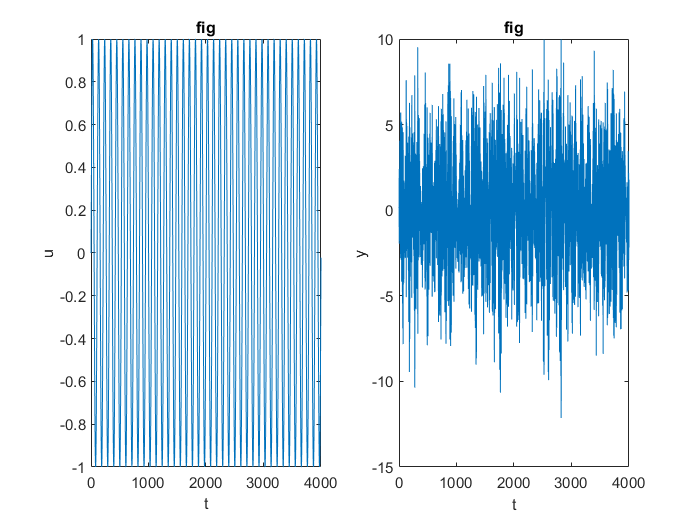

%% part 1.1
% from the true system
N = 2000;
f = 19;
offset = 0;
A = 1;
t = (0 : 1/N : 2)';
r = A * sin(2*pi*f*t) + offset; 

% r = ones([1, N]);
[u,y] = assignment_sys_36(r);


figure;
subplot(1,2,1)
plot(u)
xlabel("t");
ylabel("u");
title("fig");

subplot(1,2,2)
plot(y)
xlabel("t");
ylabel("y");
title("fig");


% we now can know M is 3


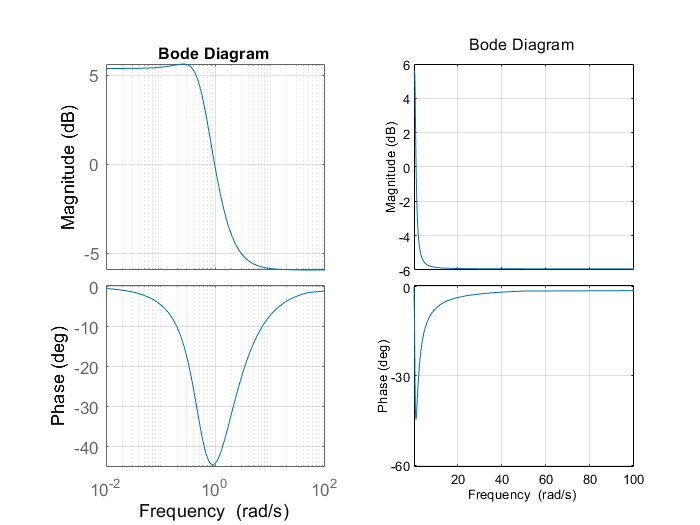

%% part 1.2
b = [0.505 1.01     0.505 ];
a = [1     0.7478   0.2722];
u1 = filter(b,a,u);

% sys = tf(b, a);
% figure;
% bode(sys);

opts = bodeoptions;
opts.FreqScale = 'linear';
figure
subplot(1,2,1)
bode(b, a)
grid on
subplot(1,2,2)
bode(b, a, opts)
grid on


% cut-off frequency is 0.72 rad/s, f = w/2/pi


%% part2
% Ts = 1;
% f = [1:128]/128*pi/Ts
% r = A * sin(2*pi*f.*t) + offset; 
% [u,y] = assignment_sys_36(r);

